clc; clear all;close all;

## 1

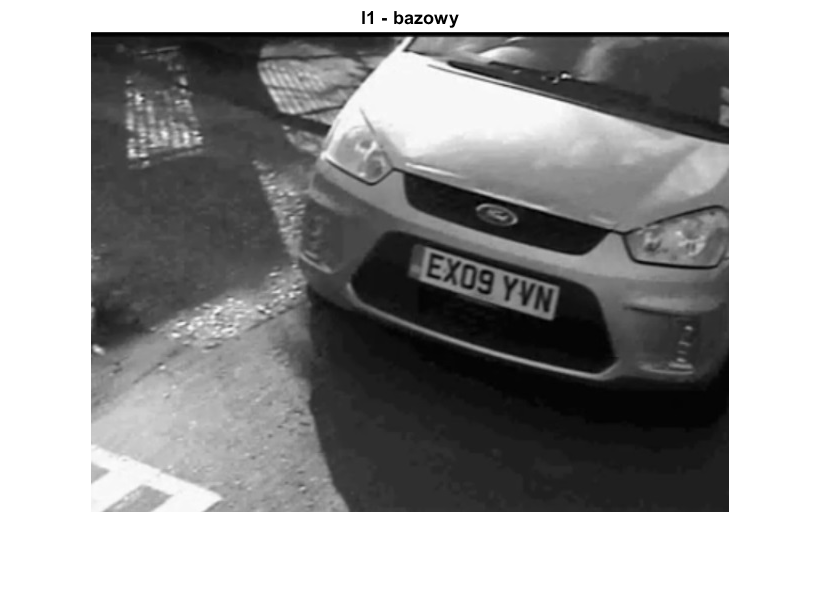


I = imread('car1.jpg');
% ---- ewentualne przejście do skali szarości
I1 =  double(rgb2gray(I));
figure; imshow(I1,[]); title('I1 - bazowy')

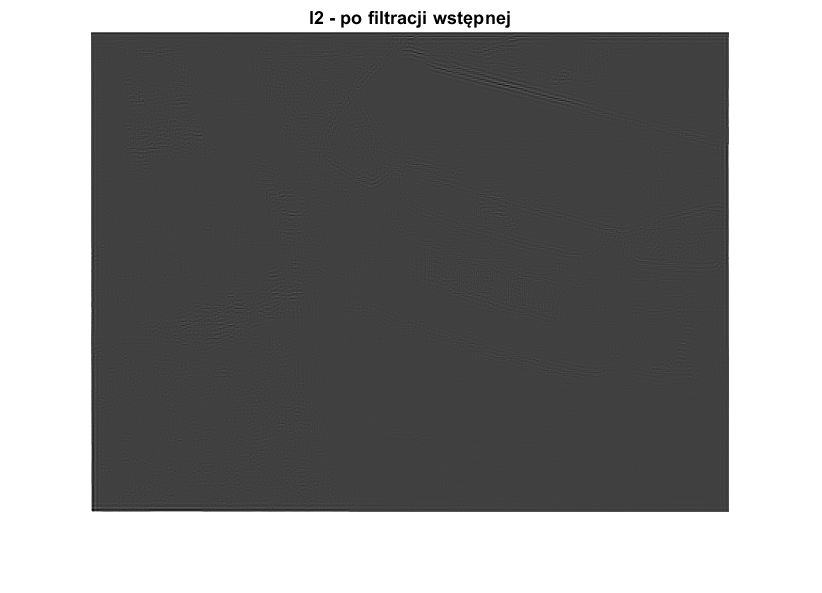


%----- filtracja wstępna:generowanie maski filtru Gaussa lub innego filtru
%h = fspecial('gaussian', 32,2 ); % generowanie maski filtru Gaussa...
% h = [];  % generowanie maski innego filtru...

[f1,f2] = freqspace(32,'meshgrid'); %Create the frequency range vectors f1 and f2 using freqspace. len 32
r = sqrt(f1.^2 + f2.^2); %Compute the distance of each position from the center frequency.

%Create a matrix Hd that contains the desired freq response
Hhp = ones(32);
Hhp(r<0.5) = 0;
win = blackman(32);

hhp = fwind1(Hhp,win);

figure;
imagesc(hhp);

I2 = filter2(hhp,I1); figure;imagesc(I2);title('I2 - po filtracji wstępnej')

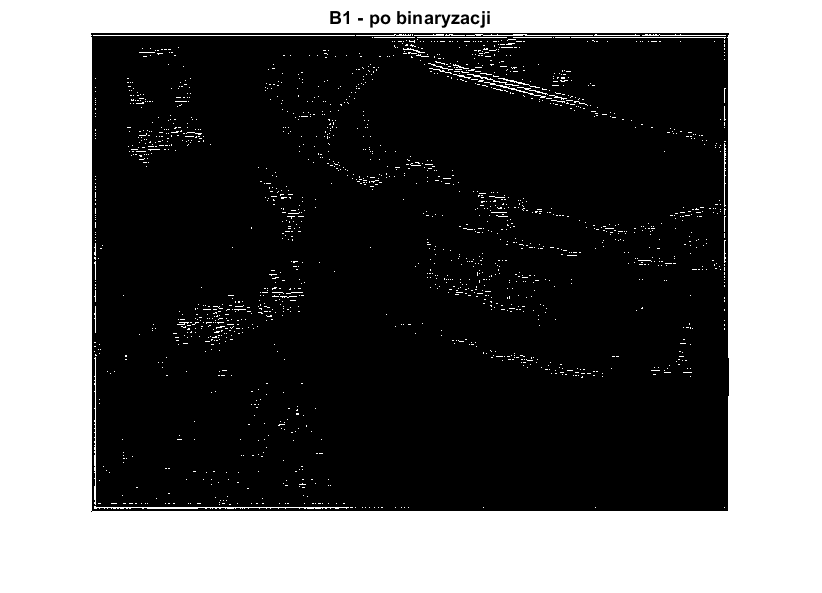

I2 = quant(I2,1); % kwantyzacja po filtracji [0 255]


 % -----  dobór progu ------
 %image = figure;
 %imshow(I2,[]);
 %imcontrast(image);

lt = 3;      % dolny prog binaryzacji
ut = 90;     % gorny prog binaryzacji

% ----- binaryzacja -------
B1 = I2; 
B1(B1<lt)=0; % usunięcie pikseli o wartościach mniejszych od lt 
B1(B1>ut)=0; % usunięcie pikseli o wartościach większych od ut 
B1(B1>0) = 1; % przypisanie pozostałym o wartościom 1
figure;imshow(B1,[]);title('B1 - po binaryzacji')

## 2

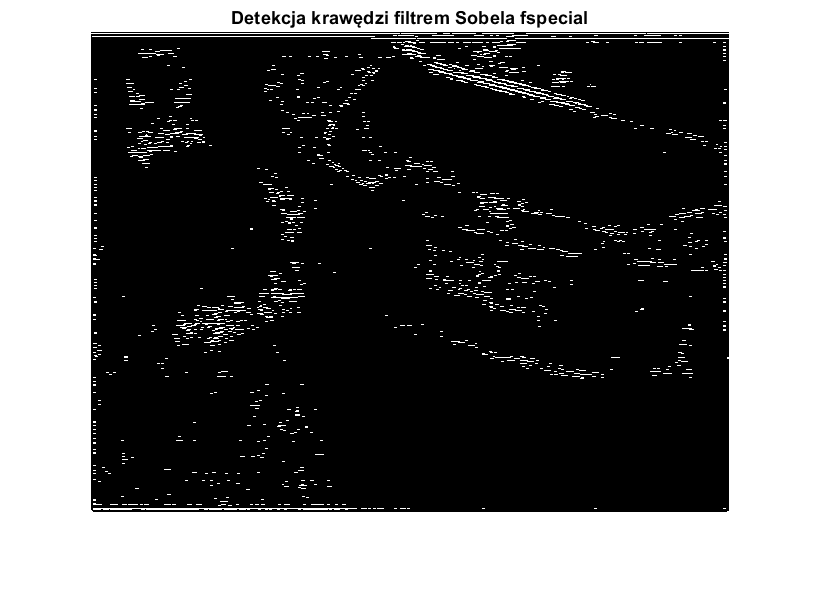


% -- detekcja krawędzi (kolejność i liczba iteracji do wyboru):
powtorzenia = 2;

sobel = fspecial('sobel');
Isobf = imfilter(B1,sobel);
prewitt = fspecial('prewitt');
Iprewitt = imfilter(B1,prewitt);
figure; imshow(Isobf); title('Detekcja krawędzi filtrem Sobela fspecial')

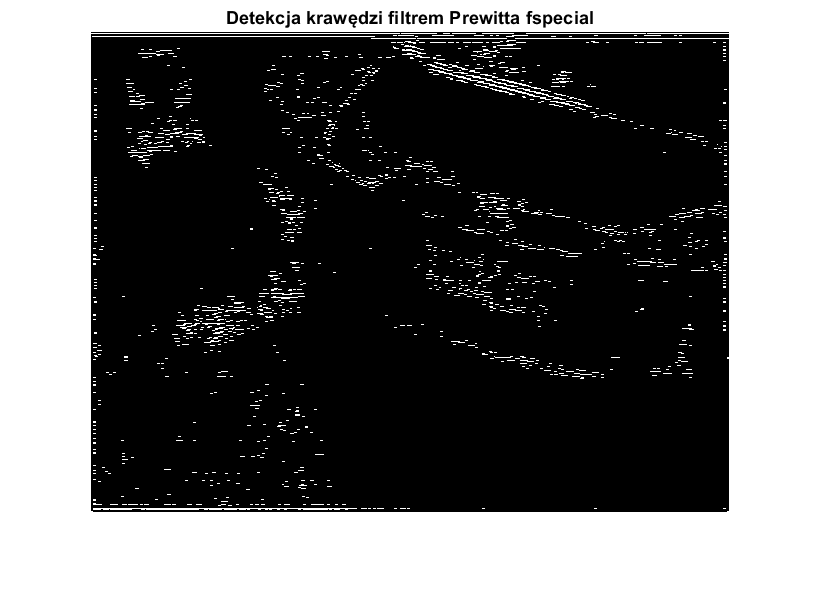

figure; imshow(Iprewitt); title('Detekcja krawędzi filtrem Prewitta fspecial')

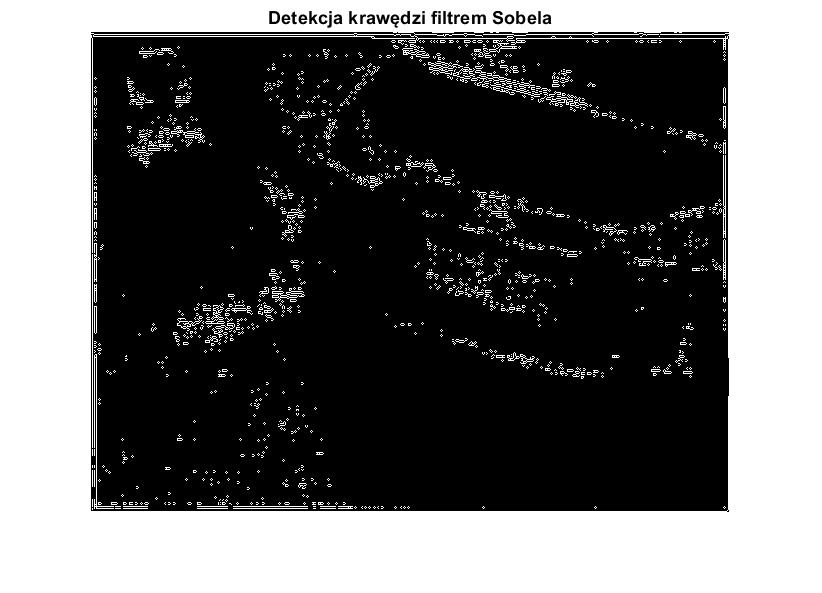

Isob = edge(B1,'sobel'); figure; imshow(Isob,[]); title('Detekcja krawędzi filtrem Sobela')

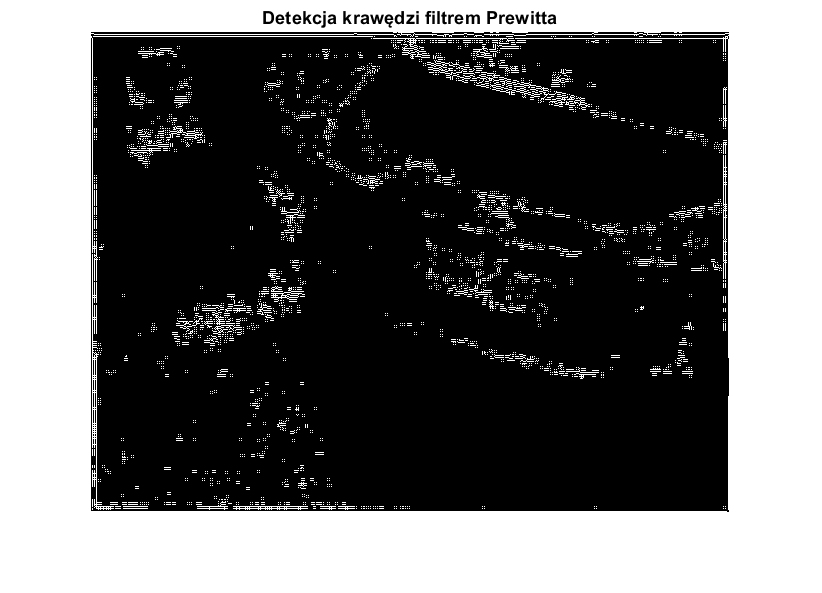

Ipre = edge(B1,'prewitt'); figure; imshow(Ipre,[]); title('Detekcja krawędzi filtrem Prewitta')

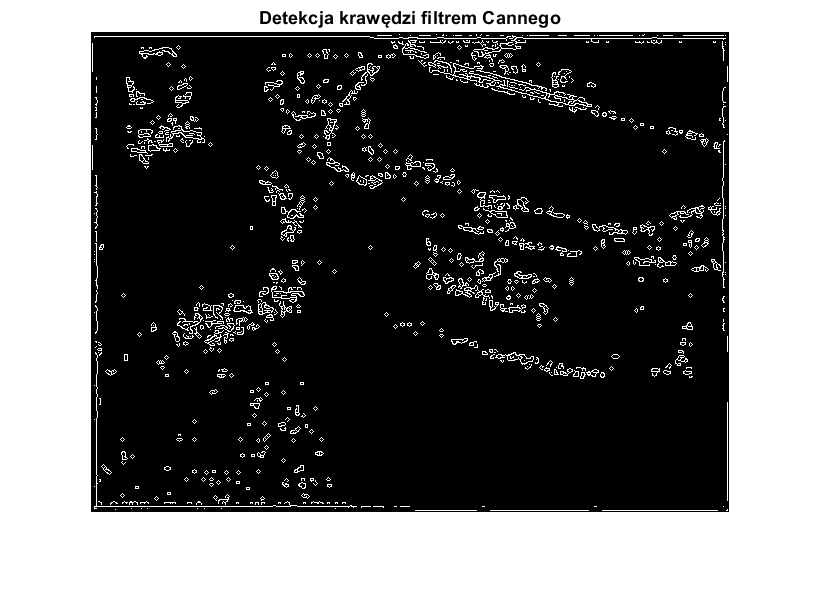

Ican = edge(B1,'canny' ); figure; imshow(Ican,[]); title('Detekcja krawędzi filtrem Cannego')

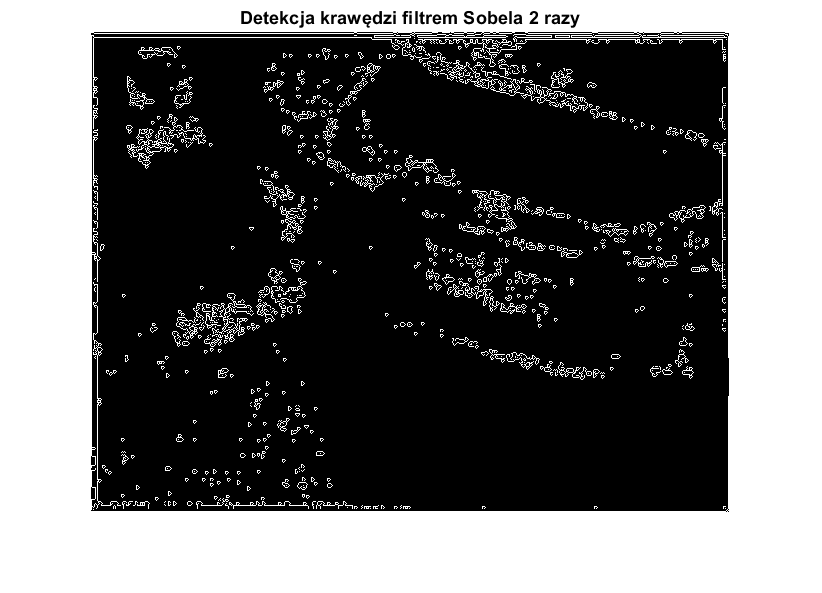


powtorzenia = powtorzenia-1;
for n = 1: powtorzenia 
    Isob = edge(Isob,'sobel');
    Ipre = edge(Ipre,'prewitt');
    Ican = edge(Ican,'canny' );
end

figure; imshow(Isob,[]); title('Detekcja krawędzi filtrem Sobela 2 razy')

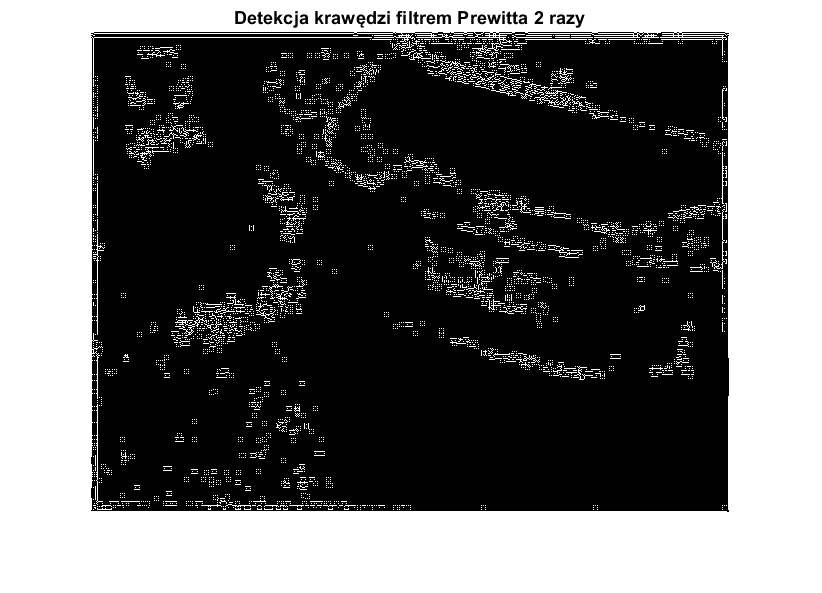

figure; imshow(Ipre,[]); title('Detekcja krawędzi filtrem Prewitta 2 razy')

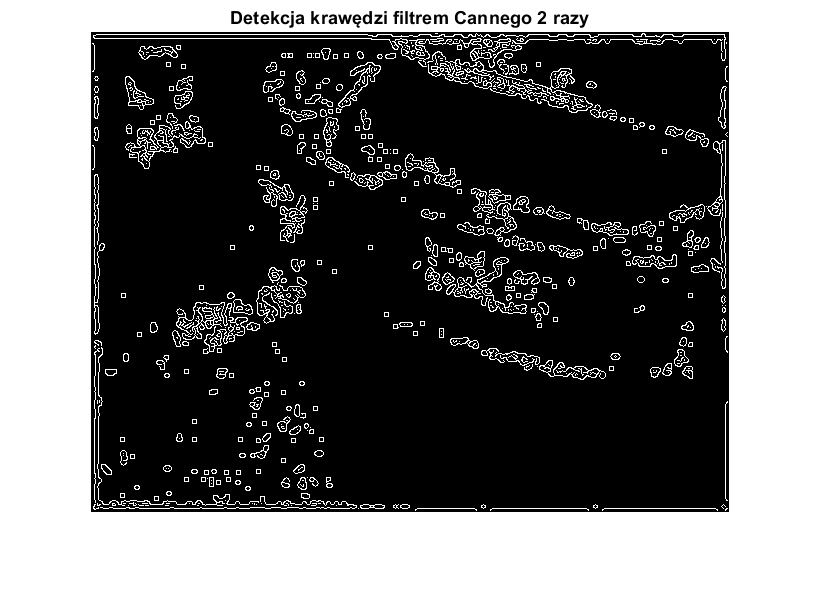

figure; imshow(Ican,[]); title('Detekcja krawędzi filtrem Cannego 2 razy')

## 3

% -- operacje morfologiczne (kolejność i liczba iteracji do wyboru):
%dyl = bwmorph(B1,'dilate',1);figure;imshow(B1,[]);title('B1 - po operacji morfologicznej dylatacji')
%ero = bwmorph(B1,'erode',1);figure;imshow(B1,[]);title('B1 - po operacji morfologicznej erozji')
%fill = imfill(B1,4,'holes');figure;imshow(B1,[]);title('B1 - po operacji morfologicznej wypełanienia')
%B1 = bwareaopen(B1, 50 ); figure;imshow(B1,[]);title('B1 - po operacji morfologicznej usunięcia elementów o powierzchni mniejszej niż X pikseli')
